Piotr Sienkiewicz    324 887

Tadeusz Chmielik   324 856

## Analiza tętna

W zadaniu tym zmierzono tętno wykorzystując optyczną metodę i nagranie z poprzednich zajęć, ale tym razem bazowano na algorytmie FFT zamiast na zliczaniu ekstremów.

Poniższy fragment kodu jest identyczny jak ten z poprzednich zajęć.

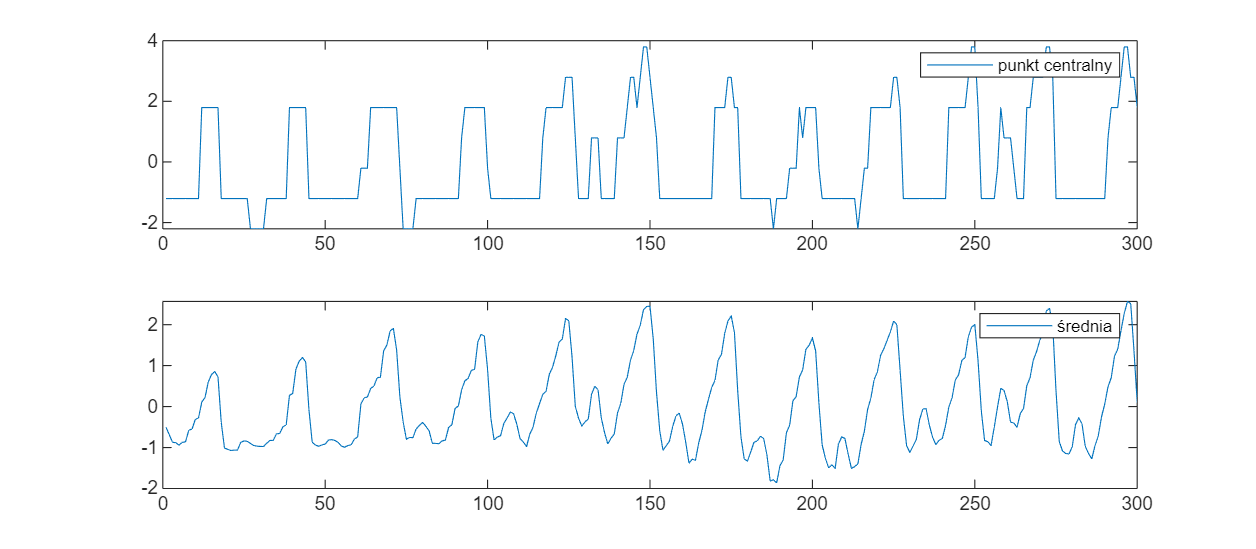

% Liczba ramek do wczytania (przy 10 sekundach i 30 FPS będzie to 300)
N = 300;

% wektor jasności
br = zeros(3, N);

use_video = 1;

if use_video
    % wczytywanie pliku wideo do analizy
    v = VideoReader('data/movie4.mp4');
    % v = VideoReader('data/movie_4.MOV');
else
    % lista obrazów do analizy
    imds = imageDatastore('./data/', 'FileExtension', '.jpg');
end

% wczytanie pierwszych N obrazów i analiza jasności
for i=1:N

    if use_video
        % dla pliku wideo ładowanie ramki z otwartego źródła
        I = read(v,i);
    else
        % wczytujemy obraz
        I = imread(imds.Files{i});
    end

    h = size(I,1);
    w = size(I,2);

    % wybieramy jedynie czerwoną składową obrazu
    I = I(:,:,1);

    % jasność punktu na środku obrazu
    br(1, i) = I(h/2, w/2);

    % wyznaczamy średnią z całego obrazu
    br(2, i) = mean(I, 'all');
end

% dla ułatwienia późniejszej analizy od razu można odjąć od sygnału składową stałą
br = br - mean(br, 2);


h = figure();
set(h,'Units','normalized','Position',[0 0 1 .7]); 
subplot(2,1,1);
plot(br(1,:));
legend('punkt centralny');
subplot(2,1,2);
plot(br(2,:));
legend('średnia');

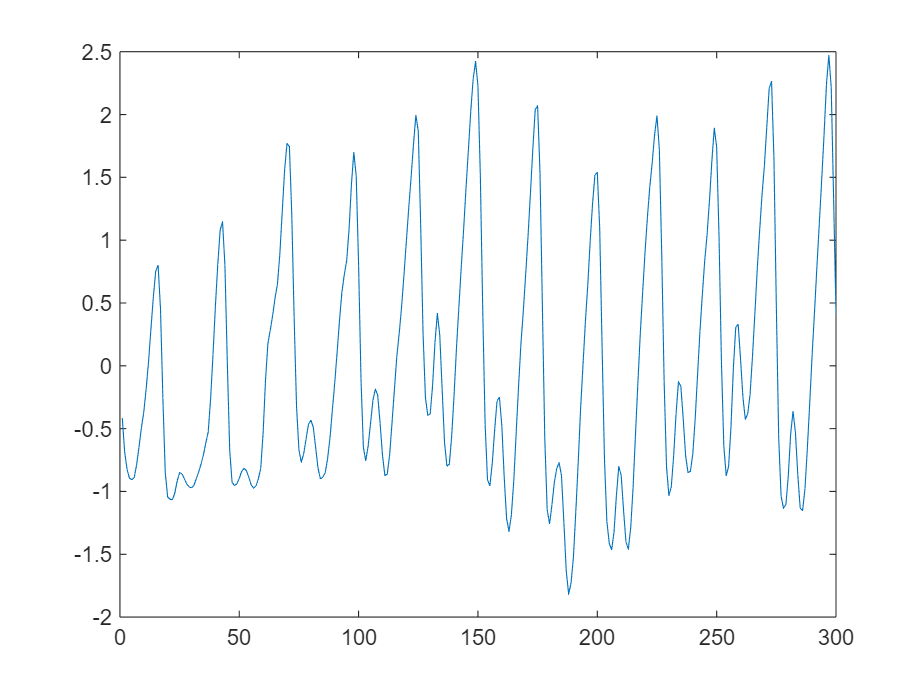

figure;
g3 = fspecial('gaussian', [1,  3], 1);
filtered_signal = conv(br(2,:), g3, 'same');

plot(filtered_signal)

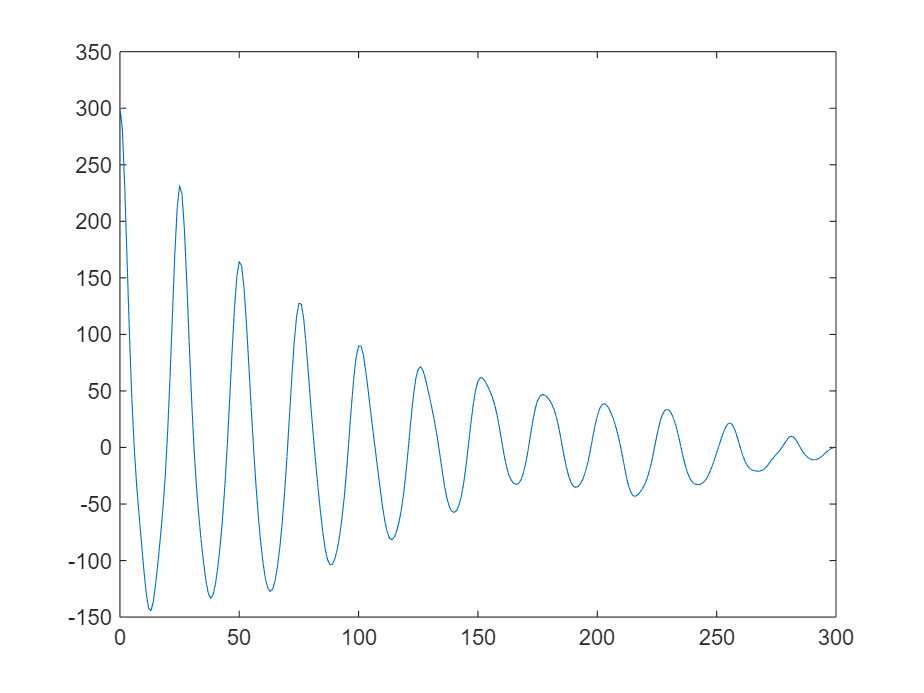

[r1, lags] = xcorr(filtered_signal);

% wycięcie jedynie dodatnich przesunięć
r1 = r1(lags >= 0);
lags = lags(lags>=0);
plot(lags, r1);

[pks, loc] = findpeaks(r1, "MinPeakDistance", 10, "MinPeakProminence", 20);
fs = 30;

% przesunięcie w sekundach
lag_s = loc(1) * 1/fs;
% częstotliwość bazowa
freq = 1/lag_s

freq = 1.1538

BPM = freq * 60

BPM = 69.2308